# Graficas de comparativas de los controladores

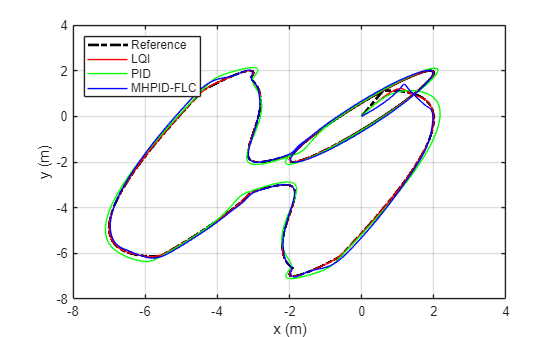

clear, clc, close all

% DATOS
load("r_lqi.mat")
load("r_pid.mat")
load("r_mhpid.mat")

controladores = {'LQI','PID','MHPID-FLC'};
R = {r_lqi, r_pid, r_mhpid};

% TIEMPO
n_points = min([length(r_lqi.Time), length(r_pid.Time), length(r_mhpid.Time)]);
t_common = linspace(0,100,n_points);

% REFERENCIA
x_ref = -0.5*max(0,min(t_common-25,10)) + 0.5*max(0,min(t_common-55,10)) ...
        - 2*sin(0.1*pi.*t_common + 0.3).*(t_common>=10);
y_ref = -0.5*max(0,min(t_common-10,10)) + 0.5*max(0,min(t_common-40,10)) ...
        - 2*sin(0.1*pi.*t_common + 0.6).*(t_common>=10);
z_ref = 1.5 + 0.1*sin(0.02*pi.*t_common + 0.3).*(t_common>=10);

figure
plot(x_ref,y_ref,'LineStyle','-.','LineWidth',2,'Color','black')
grid on
hold on
plot(r_lqi.Data(1,:), r_lqi.Data(2,:),'Color','r')
plot(r_pid.Data(1,:), r_pid.Data(2,:),'Color','g')
plot(r_mhpid.Data(1,:), r_mhpid.Data(2,:),'Color','b')

legend('Reference', 'LQI', 'PID', 'MHPID-FLC', 'Location','northwest')
xlabel('x (m)')
ylabel('y (m)')

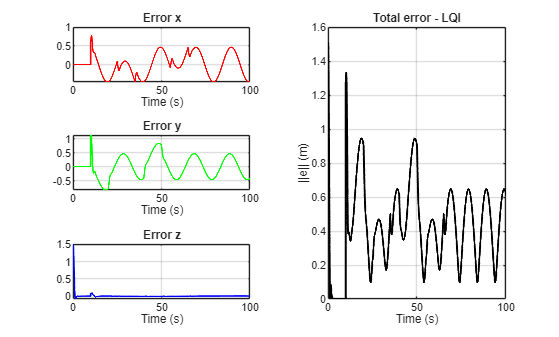

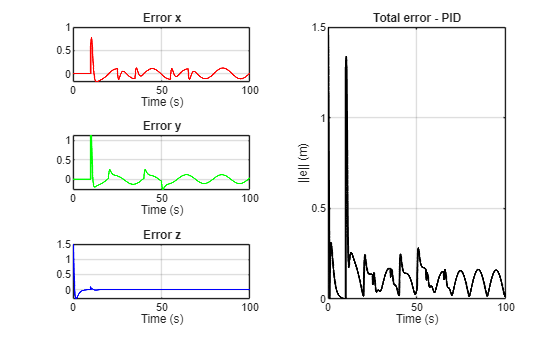

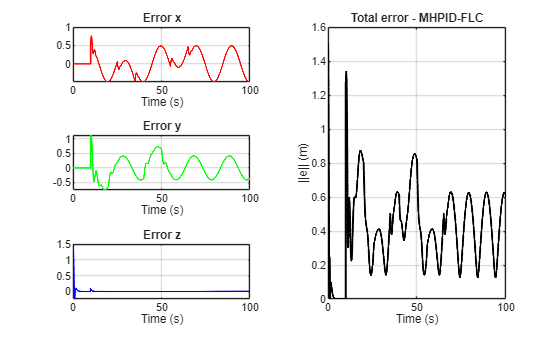


ISE_all = zeros(3,3); % ITAE por eje
ITAE_all = zeros(3,3); % ITAE por eje
ITVAE_all = zeros(3,1); % ITVAE global

for i = 1:3
    
    a = R{i};
    ti = controladores{i};
    
    % INTERPOLAR DATOS
    x_data = interp1(a.Time, a.Data(1,:), t_common, 'linear'); 
    y_data = interp1(a.Time, a.Data(2,:), t_common, 'linear'); 
    z_data = interp1(a.Time, a.Data(3,:), t_common, 'linear');     
    
    x_ref = x_ref(:); y_ref = y_ref(:); z_ref = z_ref(:);
    x_data = x_data(:); y_data = y_data(:); z_data = z_data(:);
    
    % ERROR
    e = [x_ref - x_data, y_ref - y_data, z_ref - z_data];
    e_norm = sqrt(sum(e.^2,2)); % norma
    
    t_col = t_common(:);
    
    % ÍNDICES DE DESEMPEÑO
    ISE = trapz(t_col, e.^2);   % por eje
    ITAE = trapz(t_col, t_col .* abs(e));   % por eje
    
    ISE_all(i,:) = ISE;
    ITAE_all(i,:) = ITAE;
    
    figure
    tiledlayout(3,2)

    nexttile(1)
    plot(t_common, e(:,1),'r','LineWidth',1.2)
    grid on
    title('Error x')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    nexttile(3)
    plot(t_common, e(:,2),'g','LineWidth',1.2)
    grid on
    title('Error y')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    nexttile(5)
    plot(t_common, e(:,3),'b','LineWidth',1.2)
    grid on
    title('Error z')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    % NORMA
    nexttile([3 1])
    plot(t_common, e_norm,'k','LineWidth',1.5)
    grid on
    title(['Total error - ' ti])
    xlabel('Time (s)')
    ylabel('||e|| (m)')
        
end

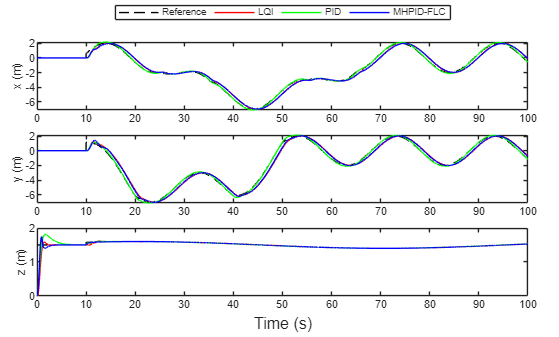


figure
t = tiledlayout(3,1,"TileSpacing","compact","Padding","compact"); 

ax1 = nexttile(t,1);
h1 = plot(ax1, t_common, x_ref,'--black', ...
    r_lqi.Time, r_lqi.Data(1,:),'r', ...
    r_pid.Time, r_pid.Data(1,:),'g', ...
    r_mhpid.Time, r_mhpid.Data(1,:),'b');
ylabel(ax1,'x (m)')

ax2 = nexttile(t,2);
h2 = plot(ax2, t_common, y_ref,'--black', ...
    r_lqi.Time, r_lqi.Data(2,:),'r', ...
    r_pid.Time, r_pid.Data(2,:),'g', ...
    r_mhpid.Time, r_mhpid.Data(2,:),'b');
ylabel(ax2,'y (m)')

ax3 = nexttile(t,3);
h3 = plot(ax3, t_common, z_ref,'--black', ...
    r_lqi.Time, r_lqi.Data(3,:),'r', ...
    r_pid.Time, r_pid.Data(3,:),'g', ...
    r_mhpid.Time, r_mhpid.Data(3,:),'b');
ylabel(ax3,'z (m)')

% Etiqueta X compartida
xlabel(t,'Time (s)')

% Crear leyenda a partir de los handles (combina h1 y h2 si quieres todas las líneas)
allHandles = [h1(:); h2(:); h3(:)];                    % juntar handles en un vector
labels = {'Reference','LQI','PID','MHPID-FLC'}; % etiquetas (una por serie)
lgd = legend(allHandles(1:4), labels, ...      % usa solo una copia por serie si están duplicadas
    'Location','northoutside', 'Orientation','horizontal');

% Opcional: colocar la leyenda en una baldosa del layout (si prefieres)
lgd.Layout.Tile = "north";   % "north", "east", "south", "west"


table(ISE_all(:,1), ISE_all(:,2), ISE_all(:,3),'VariableNames', {'x', 'y', 'z'}, 'RowNames', {'LQGI', 'PID', 'MHPID-FLC'})

ans = 3×3 table
                   x         y          z   
                 ______    ______    _______

    LQGI         8.4309    15.483     1.1215
    PID           1.087    1.6953    0.97728
    MHPID-FLC    9.2773    12.536    0.80624


table(ITAE_all(:,1), ITAE_all(:,2), ITAE_all(:,3),'VariableNames', {'x', 'y', 'z'}, 'RowNames', {'LQGI', 'PID', 'MHPID-FLC'})

ans = 3×3 table
                   x         y         z   
                 ______    ______    ______

    LQGI           1331    1642.2    14.302
    PID          343.93    399.58    4.4922
    MHPID-FLC    1402.4      1465    10.604


## Perturbacion

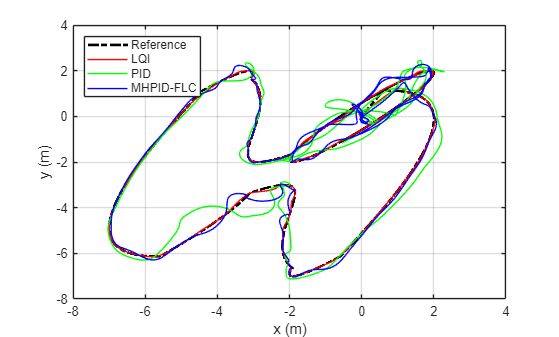

load("r_lqi_p.mat")
load("r_pid_p.mat")
load("r_mhpid_p.mat")

R = {r_lqi_p, r_pid_p, r_mhpid_p};

% TIEMPO
n_points = min([length(r_lqi_p.Time), length(r_pid_p.Time), length(r_mhpid_p.Time)]);
t_common = linspace(0,100,n_points);

% REFERENCIA
x_ref = -0.5*max(0,min(t_common-25,10)) + 0.5*max(0,min(t_common-55,10)) ...
        - 2*sin(0.1*pi.*t_common + 0.3).*(t_common>=10);
y_ref = -0.5*max(0,min(t_common-10,10)) + 0.5*max(0,min(t_common-40,10)) ...
        - 2*sin(0.1*pi.*t_common + 0.6).*(t_common>=10);
z_ref = 1.5 + 0.1*sin(0.02*pi.*t_common + 0.3).*(t_common>=10);

figure
plot(x_ref,y_ref,'LineStyle','-.','LineWidth',2,'Color','black')
grid on
hold on
plot(r_lqi_p.Data(1,:), r_lqi_p.Data(2,:),'Color','r')
plot(r_pid_p.Data(1,:), r_pid_p.Data(2,:),'Color','g')
plot(r_mhpid_p.Data(1,:), r_mhpid_p.Data(2,:),'Color','b')

legend('Reference', 'LQI', 'PID', 'MHPID-FLC', 'Location','northwest')
xlabel('x (m)')
ylabel('y (m)')

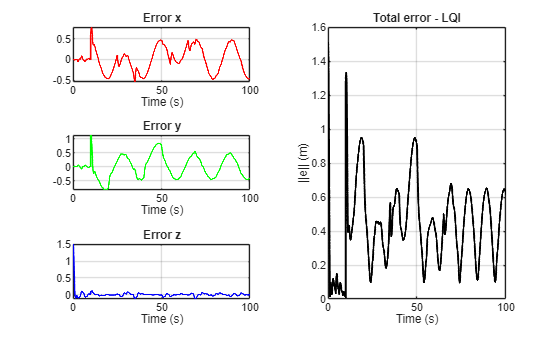

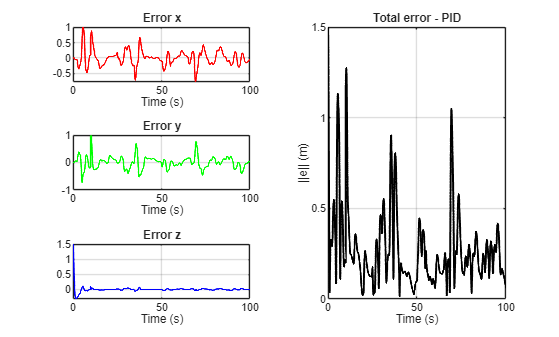

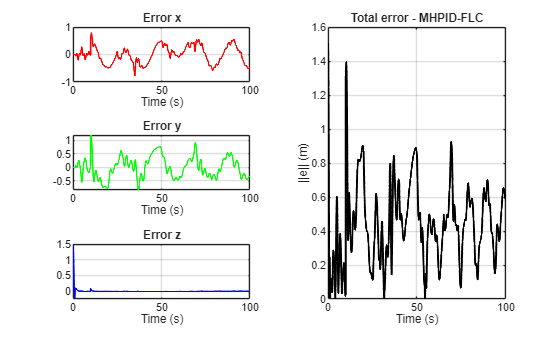


ITAE_all = zeros(3,3); % ITAE por eje
ISE_all = zeros(3,3); % ITAE por eje

for i = 1:3
    
    a = R{i};
    ti = controladores{i};
    
    % INTERPOLAR DATOS
    x_data = interp1(a.Time, a.Data(1,:), t_common, 'linear'); 
    y_data = interp1(a.Time, a.Data(2,:), t_common, 'linear'); 
    z_data = interp1(a.Time, a.Data(3,:), t_common, 'linear'); 
    
    x_ref = x_ref(:); y_ref = y_ref(:); z_ref = z_ref(:);
    x_data = x_data(:); y_data = y_data(:); z_data = z_data(:);
    
    % ERROR
    e = [x_ref - x_data, y_ref - y_data, z_ref - z_data];
    e_norm = sqrt(sum(e.^2,2)); % norma
    
    t_col = t_common(:);
    
    % ÍNDICES DE DESEMPEÑO
    ISE = trapz(t_col, e.^2);   % por eje
    ITAE = trapz(t_col, t_col .* abs(e));   % por eje
    
    ISE_all(i,:) = ISE;
    ITAE_all(i,:) = ITAE;
    
    figure
    tiledlayout(3,2)

    nexttile(1)
    plot(t_common, e(:,1),'r','LineWidth',1.2)
    grid on
    title('Error x')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    nexttile(3)
    plot(t_common, e(:,2),'g','LineWidth',1.2)
    grid on
    title('Error y')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    nexttile(5)
    plot(t_common, e(:,3),'b','LineWidth',1.2)
    grid on
    title('Error z')
    xlabel('Time (s)')
    %ylabel('Error (m)')

    % NORMA
    nexttile([3 1])
    plot(t_common, e_norm,'k','LineWidth',1.5)
    grid on
    title(['Total error - ' ti])
    xlabel('Time (s)')
    ylabel('||e|| (m)')
    
end

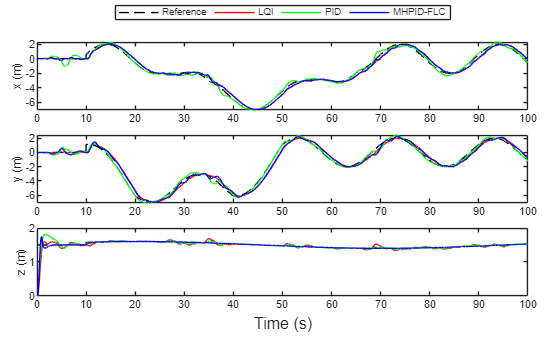


figure
t = tiledlayout(3,1,"TileSpacing","compact","Padding","compact");

ax1 = nexttile(t,1);
h1 = plot(ax1, t_common, x_ref,'--black', ...
    r_lqi_p.Time, r_lqi_p.Data(1,:), 'r', ...
    r_pid_p.Time, r_pid_p.Data(1,:), 'g', ...
    r_mhpid_p.Time, r_mhpid_p.Data(1,:), 'b');
ylabel(ax1,'x (m)')

ax2 = nexttile(t,2);
h2 = plot(ax2, t_common, y_ref,'--black', ...
    r_lqi_p.Time, r_lqi_p.Data(2,:),'r', ...
    r_pid_p.Time, r_pid_p.Data(2,:), 'g', ...
    r_mhpid_p.Time, r_mhpid_p.Data(2,:),'b');
ylabel(ax2,'y (m)')

ax3 = nexttile(t,3);
h3 = plot(ax3, t_common, z_ref,'--black', ...
    r_lqi_p.Time, r_lqi_p.Data(3,:),'r', ...
    r_pid_p.Time, r_pid_p.Data(3,:),'g', ...
    r_mhpid_p.Time, r_mhpid_p.Data(3,:),'b');
ylabel(ax3,'z (m)')

% Etiqueta X compartida
xlabel(t,'Time (s)')

% Crear leyenda a partir de los handles (combina h1 y h2 si quieres todas las líneas)
allHandles = [h1(:); h2(:); h3(:)];                    % juntar handles en un vector
labels = {'Reference','LQI','PID','MHPID-FLC'}; % etiquetas (una por serie)
lgd = legend(allHandles(1:4), labels, ...      % usa solo una copia por serie si están duplicadas
    'Location','northoutside', 'Orientation','horizontal');

% Opcional: colocar la leyenda en una baldosa del layout (si prefieres)
lgd.Layout.Tile = "north";   % "north", "east", "south", "west"


table(ISE_all(:,1), ISE_all(:,2), ISE_all(:,3),'VariableNames', {'x', 'y', 'z'}, 'RowNames', {'LQGI', 'PID', 'MHPID-FLC'})

ans = 3×3 table
                   x         y          z   
                 ______    ______    _______

    LQGI         8.4747    15.588     1.2336
    PID          6.4212     4.875     1.0417
    MHPID-FLC    9.5212    14.806    0.80667


table(ITAE_all(:,1), ITAE_all(:,2), ITAE_all(:,3),'VariableNames', {'x', 'y', 'z'}, 'RowNames', {'LQGI', 'PID', 'MHPID-FLC'})

ans = 3×3 table
                   x         y         z   
                 ______    ______    ______

    LQGI         1332.2    1648.7       117
    PID           825.6    747.04    72.696
    MHPID-FLC    1399.1      1573     11.36
